## MSE 491 DSP - Lab Assignment 2

Authors:

- Abdullah Amjad - 301414558

- Tony Nguyen - 301286979

Created: 15 June 2022

Modified: 21 June 2022

clear all
close all
clc

## **Part 1**

% save the given sequence as xn
xn = [2,1,-1,-2];
% N= Number of intervals
N=length(xn);
% Plotting the input graph
k=0:1:3;
figure;
subplot(2,2,1)
stem(k,xn)
xlabel('time')
ylabel('amplitude')
title('Input')

% Using the Created DFT function
y=DFT(xn,N);
subplot(2,2,2)
%abs value is used because Matlab cannot plot the complex values
stem(k,abs(y))
xlabel('Frequency')
ylabel('|X(k)|')
title('DFT Magnitude response')
% Displaying the dft real and imaginary values
disp('DFT=')

DFT=


disp(y)

   0.0000 + 0.0000i
   3.0000 - 3.0000i
   2.0000 + 0.0000i
   3.0000 + 3.0000i




% Using the Built in fft function to compare the results

x =fft(xn,N);
subplot(2,2,3)
stem(k,abs(x))
xlabel('Frequency')
ylabel('|X(k)|')
title('FFT Magnitude Response')
% Displaying the FFt real and imaginary values
disp('FFT=')

FFT=


disp(x)

   0.0000 + 0.0000i   3.0000 - 3.0000i   2.0000 + 0.0000i   3.0000 + 3.0000i



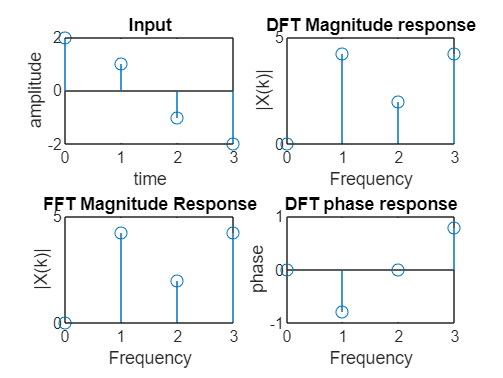


% Plotting the phase response of the dft 
subplot(2,2,4)
stem(k,angle(y))
xlabel('Frequency')
ylabel('phase')
title('DFT phase response')
hold off

## **Part 2**

% Saving the output from part 1 as a
a = [0,3-3i,2,3+3i];
L=length(a);
t=0:1:L-1;

% Computing the 4 point Inverse dft by creating a IDFT function
b=IDFT(a,L);
figure;
subplot(2,1,1)
stem(t,b)

% A warning is seen for using the real components but it can be ignored as
% the complex part is not important
xlabel('time')
ylabel('amplitude')
title('IDFT')
% Displaying the obtained values for IDFT
disp('IDFT =')

IDFT =


disp(b)

   2.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -2.0000 + 0.0000i



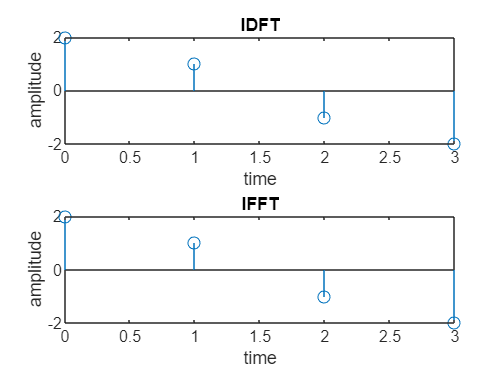

% Comparing the results with the ifft function
z=ifft(a,L);
subplot(2,1,2)
stem(t,z)
xlabel('time')
ylabel('amplitude')
title('IFFT')

% Displaying the obtained values for ifft
disp('IFFT =')

IFFT =


disp(b)

   2.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -2.0000 + 0.0000i



## **Part 3**

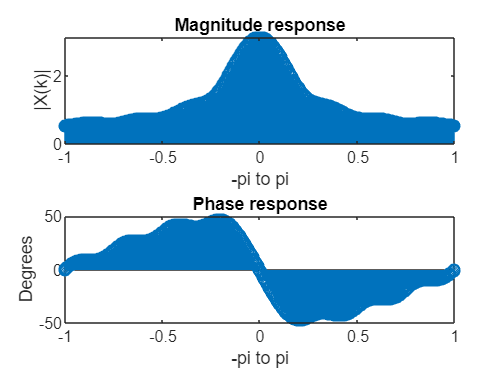

% define omega from -pi to pi because the magnitude response would repeat
% if we increase the interval
w = -pi:0.01:pi;
% define the transfer function/analytical expression
X = (1-(0.7*exp(-1j*w)).^8)./(1-0.7*exp(-1j*w));

% ploting the magnitude response
figure;                 
subplot(2,1,1);
stem((w/pi),abs(X));
xlabel('-pi to pi');
ylabel('|X(k)|')
title('Magnitude response');

% ploting the frequency response
subplot(2,1,2);
stem((w/pi),rad2deg(angle(X)));
xlabel('-pi to pi');
title('Phase response');
ylabel('Degrees');

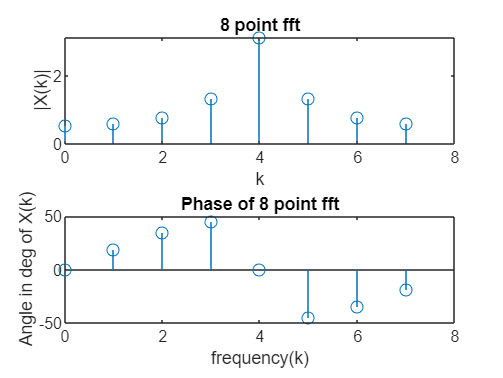


% define n
N = 8;
n = 0:1:7;
% define x as provided in the transefer function
x = (0.7).^n;
% 8 point fft
Y = fftshift(fft(x,N));
% plot the magnitude respnse for N=8
figure;
subplot(2,1,1);
stem(n,abs(Y));
title('Magitude of 8 point fft')
xlabel('frequncy(k)');
ylabel('|X(k)|');
title('8 point fft');

% plotting the phase response for N=8
subplot(2,1,2);
stem(n,rad2deg(angle(Y)));
title('Phase of 8 point fft')
xlabel('frequency(k)');
ylabel('Angle in deg of X(k)');

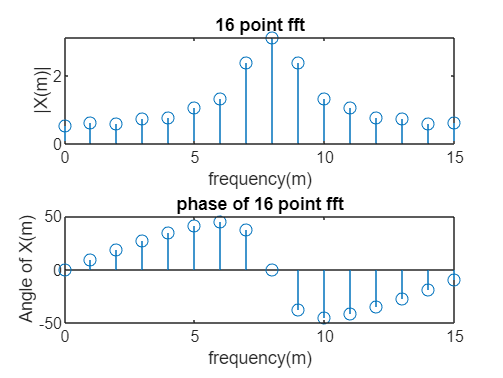


% 16 point fft
M=16;
m=0:1:15;
Z = fftshift(fft(x,M));
% plot the magnitude for M =16
figure;
subplot(2,1,1);
stem(m,abs(Z));
xlabel('frequency(m)');
ylabel('|X(m)|');
title('16 point fft');
%plotting the phase in deg for M=16
subplot(2,1,2);
stem(m,rad2deg(angle(Z)));
title('phase of 16 point fft')
xlabel('frequency(m)');
ylabel('Angle of X(m)');


% Zero padding referes to the addding of zero values in order to increase
% the samples of a given signal.
% Zero-padding is changing the DFT length N without adding more signal, 
% which just results in a denser sampling of the underlying DTFT of the signal.
% By this method we can obtain a better representation of magnitude and
% phase response. However it does not increase the resolution of frquency
% but makes the frequency spectrum more smoother.

## Q4 Telephone

%% Declare time interval
t_min = 0;
t_max = 16e-3;
t_size = abs(t_min) + abs(t_max);
Fs = 2^15; %sampling frequency
ttl_smpl=round(Fs*t_size);
t = linspace(t_min,t_max,ttl_smpl);

%4a: See below for dial tone generator

%4b: Play tone of random number
r = randi([1,10],1) - 1; %b/c randii range can only start at one, need to minus one
y = dial_tone(r,t);

A = 0.125;
tone = A*y;

%expand tone to play for one second
for i = 1:round(1/t_size)
    tone = [tone A*y];
end

sound(tone,Fs);

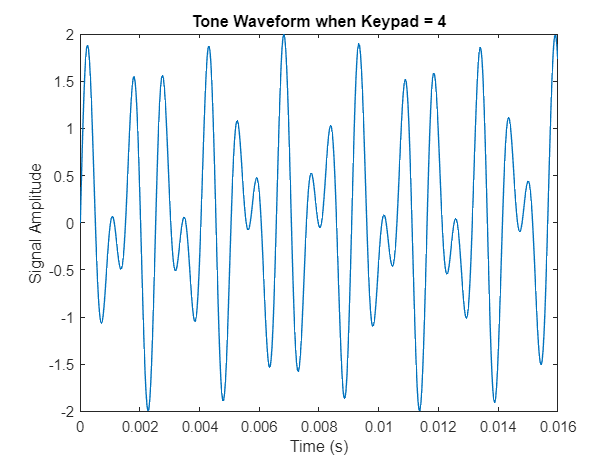

%4c: Plot tone waveform
plot(t,y)
title(['Tone Waveform when Keypad = ', num2str(r)])
xlabel('Time (s)')
ylabel('Signal Amplitude')

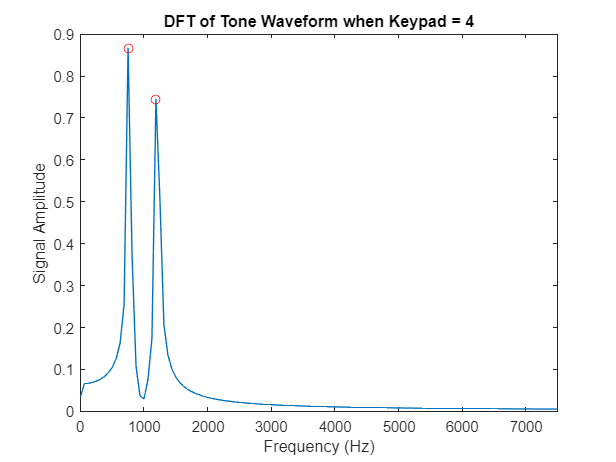

%4d and e: Plot DFT and find frequencies of tone
L = ttl_smpl;
%Y = fft(y); %for comparison's sake
Y = DFT(y,L).';
    
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

[pks, locs] = findpeaks(P1);
pk_f = f(locs); %Frequencies of dial tone
plot(f,P1,pk_f,pks,'or')
xlim([0 7500])
title(['DFT of Tone Waveform when Keypad = ', num2str(r)])
xlabel('Frequency (Hz)')
ylabel('Signal Amplitude')

Functions:

DFT function:

function X=DFT(x,N)
Nx=length(x);
if(N<Nx)
    error('N must be greater than or equal to the length of x')
end

X=zeros(N,1);
for k = 0:N-1
    for n = 0:N-1
        X(k+1) = X(k+1) + x(n+1)*exp((-2j*pi*n*k)/Nx);
    end
end
end

IDFT function:

function X = IDFT(x,N)
X= zeros(1,N);
for k = 0:N-1
    for n = 0:N-1
         X(k+1) = X(k+1) + ((1/N)*x(n+1))*exp((2*(1i)*pi*n*k)/N);
    end
end
end

Dial Tone Function

function y = dial_tone(x,t)
%keypad in matrix form
keypad = [ 1,   2,   3;
           4,   5,   6;
           7,   8,   9;
          nan,  0,  nan;];

[m,n] = find(keypad == x); %row and column of inputted number

%Frequency (Hz) of number dependent on location of its row and column in keypad
switch m
    case 1
        f1 = 697;
    case 2
        f1 = 770;
    case 3
        f1 = 852;
    case 4
        f1 = 941;
end

switch n
    case 1
        f2 = 1209;
    case 2
        f2 = 1336;
    case 3
        f2 = 1477;
end

%Create signal
s1 = sin(2*pi*f1*t);
s2 = sin(2*pi*f2*t); 
y = s1 + s2;

end